# BHZ_2D

BHZ model

## BHZ model

### Useful matrix

clear;
%% useful tool
s_0   = pauli_matric(0)  ;  s_x = pauli_matric(1);  s_y =  pauli_matric(2) ;  s_z = pauli_matric(3);
sigma_0 = pauli_matric(0);sigma_x =  pauli_matric(1);sigma_y =  pauli_matric(2);sigma_z = pauli_matric(3);
tau_0   = pauli_matric(0);  tau_x =  pauli_matric(1);  tau_y =  pauli_matric(2);  tau_z = pauli_matric(3);

### k·p model

syms C0 C1 C2 real;
syms M0 M1 M2 real;
syms A B1 B2 real;
syms k_x k_y k_z real;
%
M       = M0-M2*(k_x^2+k_y^2);
E0k     = C0+C2*(k_x^2+k_y^2);
k_plus  = k_x + 1i* k_y;
k_minus = k_x - 1i* k_y;
%
BHZ = HK(4,2)

BHZ =   HK - 属性:

           Rank: 2
          Kinds: 10
          HcoeL: [4×4×10 sym]
          HnumL: [4×4×10 double]
          HstrL: ["1"    "x"    "y"    "z"    "x*y"    "x*z"    "y*z"    "X"    "Y"    "Z"]
           Hfun: []
          HsymL: [1    k_x    k_y    k_z    k_x*k_y    k_x*k_z    k_y*k_z    k_x^2    k_y^2    k_z^2]
         Hk_sym: [4×4 sym]
         Hk_num: []
       Hk_latex: '\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)'
      Basis_num: 4
             Rm: [3×3 double]
             Gk: [3×3 double]
    symvar_list: [1×0 sym]

\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)

%
BHZ = BHZ ...
    +Term(A*k_x ,sigma_z*tau_x )...
    +Term(A*k_y ,sigma_0*tau_y )...
    +Term(E0k   ,sigma_0*tau_0 )...
    +Term(M     ,sigma_0*tau_z )...
    ;

Setting 1/1 term into HK ...


Setting 1/1 term into HK ...


Setting 3/3 term into HK ...


Setting 3/3 term into HK ...


BHZ_sym = simplify(BHZ.sym())

$$BHZ\_sym = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & A\,\left(-k_{y}\,\mathrm{i}+k_{x}\right) & 0 & 0\\ A\,\left(k_{y}\,\mathrm{i}+k_{x}\right) & \sigma_{1} & 0 & 0\\ 0 & 0 & \sigma_{2} & -A\,\left(k_{y}\,\mathrm{i}+k_{x}\right)\\ 0 & 0 & -A\,\left(-k_{y}\,\mathrm{i}+k_{x}\right) & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=C_{0}-M_{0}+{k_{x}}^{2}\,\left(M_{2}+C_{2}\right)+{k_{y}}^{2}\,\left(M_{2}+C_{2}\right)\\ \sigma_{2}=C_{0}+M_{0}+{k_{x}}^{2}\,\left(-M_{2}+C_{2}\right)+{k_{y}}^{2}\,\left(-M_{2}+C_{2}\right) \end{array}$$

T = Oper.time_reversal(3,double(-i*sigma_y*tau_0))

T =   Oper - 属性:

               R: [3×3 double]
               t: [0 0 0]
       conjugate: 1
    antisymmetry: 0
              Rf: []
              tf: [0 0 0]
               U: [4×4 double]

U·H(k)*·U^-1 = H(-R·k)
R = 1
U = [0 0 -1 0;0 0 0 -1;1 0 0 0;0 1 0 0]

### Bulk band

#### para

% unit eV 
C0     = -0.0   ;
M0     = -1   ;
%M0     = -0.25   ;
% unit eV Ang
A      =  1      ;
%B      =  4.1      ;
% unit eV Ang^2
C1     =  0     ;
C2     =  0     ;
M1     =  0      ;
M2     =  -0.5  ;
B1     =  0.5    ;
B2     =  0  ;
% unit    Ang
a      =  1        ;
b      =  1       ;
c      =  1        ;

### wilsonloop

BHZ = BHZ <'POSCAR';
BHZ_up = BHZ.reseq([1,2]);
BHZ_dn = BHZ.reseq([3,4]);
BHZ_n = BHZ.Subsall();
BHZ_up_n = BHZ_up.Subsall();
BHZ_dn_n = BHZ_dn.Subsall();

% [BFCAR,~,klist_l] = BHZ_n.WilsonLoop();
% vasplib.WilsonLoopPlot(BFCAR,klist_l,'Color','g');
% [BFCAR,~,klist_l] = BHZ_up_n.WilsonLoop();
% vasplib.WilsonLoopPlot(BFCAR,klist_l,'Color','r');
% [BFCAR,~,klist_l] = BHZ_dn_n.WilsonLoop();
% vasplib.WilsonLoopPlot(BFCAR,klist_l,'Color','b');

### kp2TB

BHZ_TB = BHZ.kp2TB();
BHZ_TB_up= BHZ_up.kp2TB();
BHZ_TB_dn= BHZ_dn.kp2TB();
%
%
BHZ_TB_n = BHZ_TB.Subsall();
BHZ_TB_up_n = BHZ_TB_up.Subsall();
BHZ_TB_dn_n = BHZ_TB_dn.Subsall();

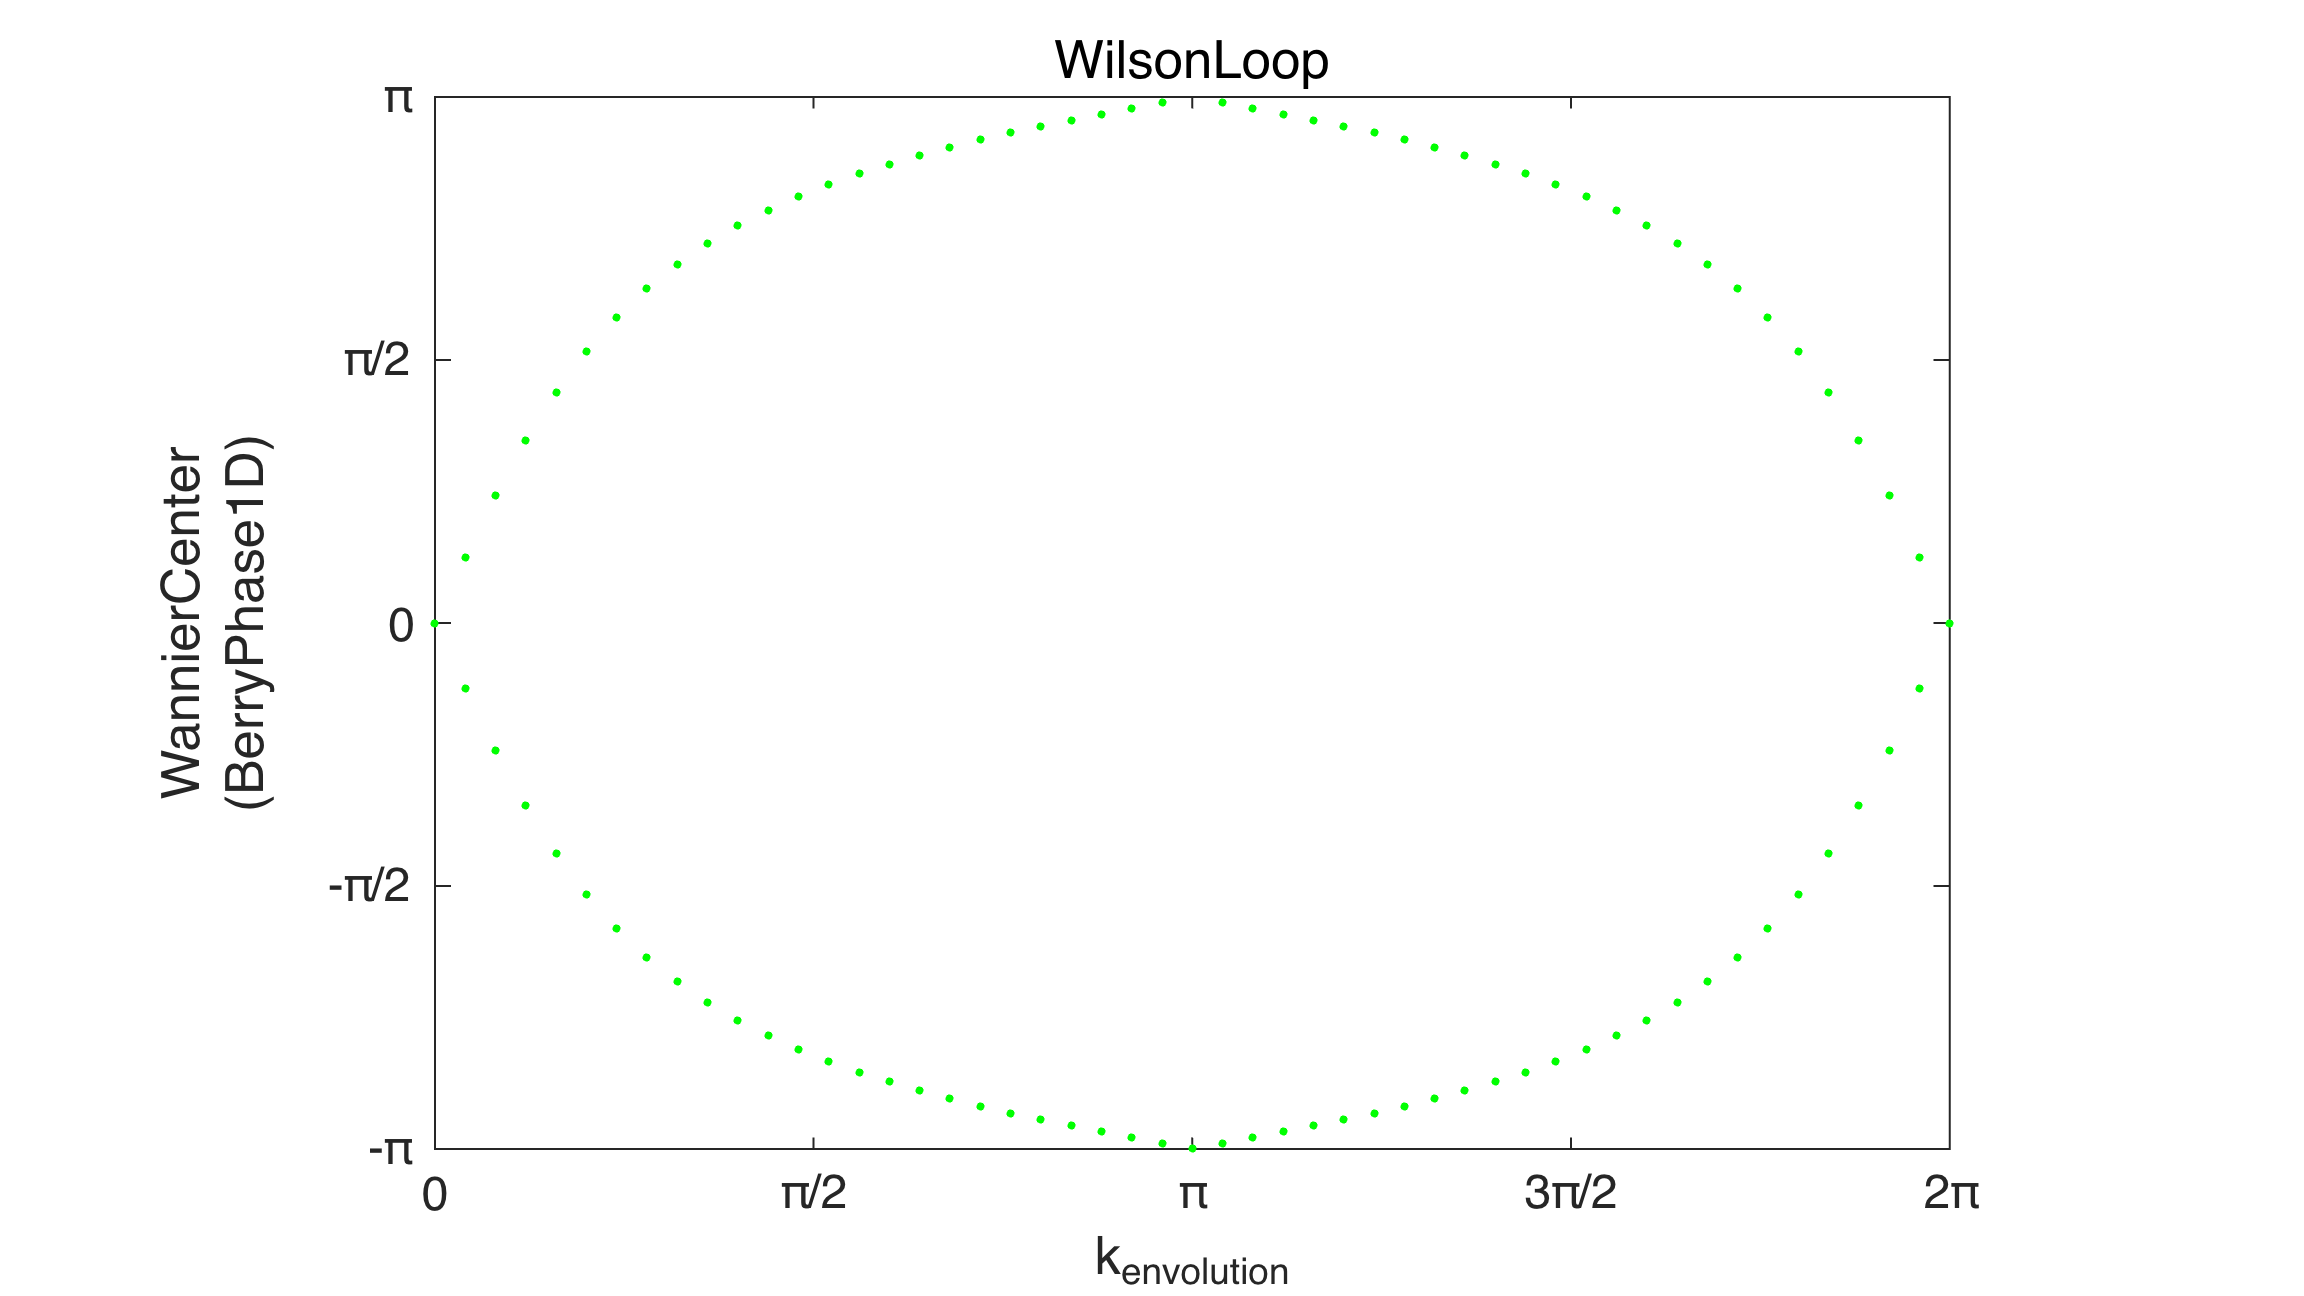

[BFCAR,~,klist_l] = BHZ_TB_n.WilsonLoop();
vasplib.WilsonLoopPlot(BFCAR,klist_l,'Color','g');

sum(BFCAR,'all')/(pi)

ans = -2.0000

[BFCAR,~,klist_l] = BHZ_TB_up_n.WilsonLoop();
sum(BFCAR,'all')/(pi)

ans = -1.0000

[fig,ax] = vasplib.WilsonLoopPlot(BFCAR,klist_l,'Color','r');
[BFCAR,~,klist_l] = BHZ_TB_dn_n.WilsonLoop();
sum(BFCAR,'all')/(pi)

ans = -1.0000

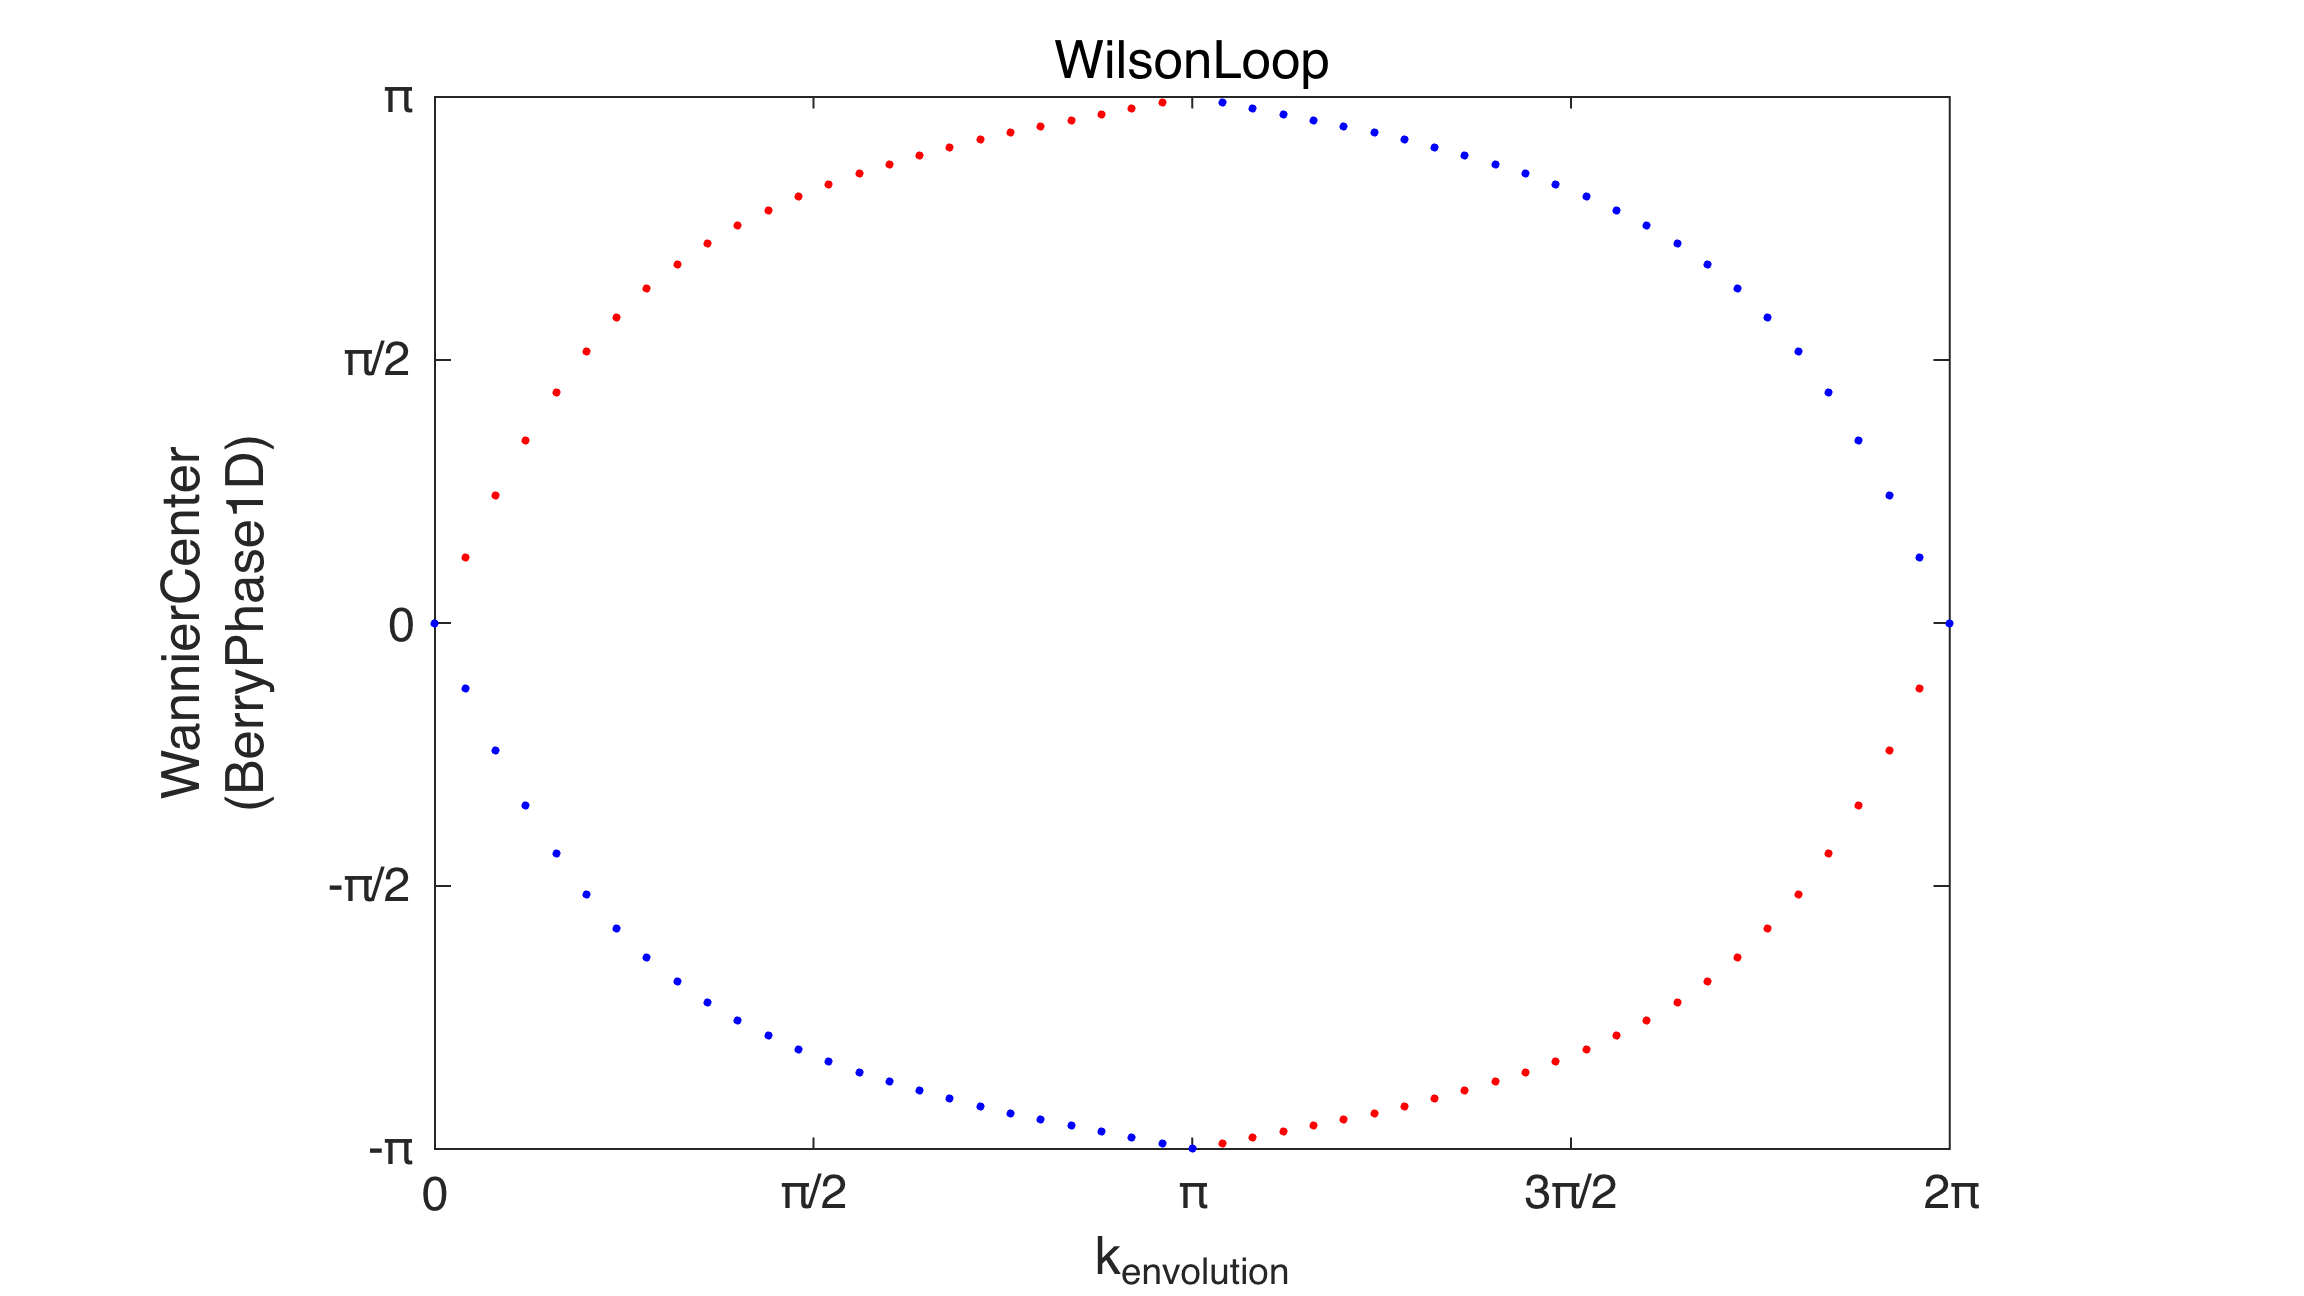

vasplib.WilsonLoopPlot(BFCAR,klist_l,'Color','b','fig',fig,'ax',ax);